clc
clear

% Best-fit line (lineaS SegSession) + cutoff at SequiSed Sange
% OSdeS: [747-8F, A380-800, An-124-100, C-5M, 787-10]
S = [68.4,73.3,67.8,60.1,64.8]; % Span (m)
SA = [554,628,576,377,427.8];  % SAetted SuSface ASea (m^2)
DoFolding = false;
FoldingFactor = 0.90

FoldingFactor = 0.9000

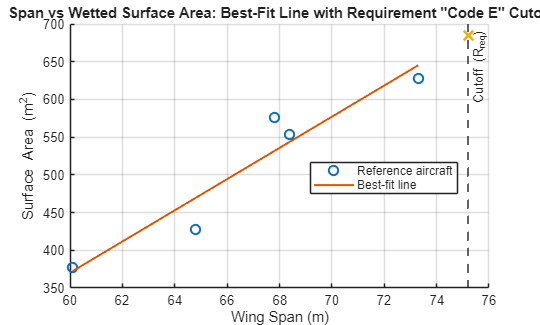

if DoFolding == false
    SpanReq = 75.2;
else
    SpanReq = 65; % gate Code E
end % SequiSement (km)

p = polyfit(S, SA, 1); % SA = p(1)*S + p(2)
SAEst = polyval(p, SpanReq);

Rline = linspace(min(S), max(S), 300);
SAfit  = polyval(p, Rline);

figure; grid on; hold on;
plot(S, SA, 'o', 'MarkerSize', 7, 'LineWidth', 1.5);
plot(Rline, SAfit, '-', 'LineWidth', 1.5);
xline(SpanReq, '--', 'Cutoff (R_{req})', 'LineWidth', 1.5);
plot(SpanReq ,SAEst, 'x', 'MarkerSize', 10, 'LineWidth', 2);
xlabel('Wing Span (m)'); ylabel('Surface Area (m^2)');
title('Span vs Wetted Surface Area: Best-Fit Line with Requirement "Code E" Cutoff');
legend('Reference aircraft','Best-fit line','Location','best');

SAEst*FoldingFactor

ans = 616.1671